# 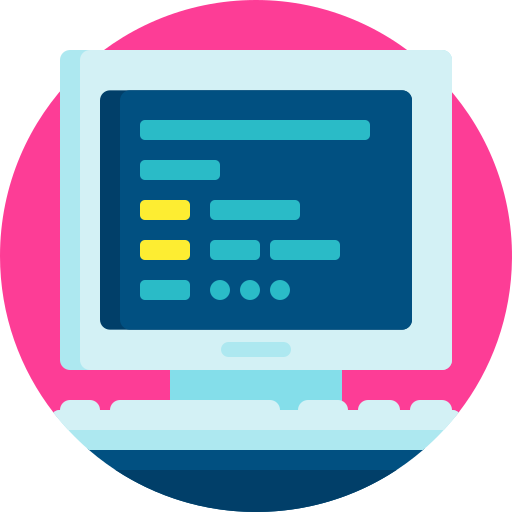

# Virtual Lab 5: Underdamped second-order systems

**This Virtual Lab covers content in Chapter 6-7 of the course notes**

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output on Right`.

- This script has been sectioned off — you can use `Run Section `(CMD/CNTL+ENTER) instead of` Run `when in a particular section. This will only evaluate code in the section. 

- This virtual lab requires the following `MATLAB` toolboxes: Control Systems Toolbox, Symbolic Math Toolbox.

- You can use the `help` function to get information on a function within the `MATLAB Command Window`, e.g. `help laplace`.

## Introduction

The underdamped second-order system, a common model for physical problems, displays unique behavior that must be itemized; a detailed description of the underdamped response is necessary for both analysis and design

## Determining the analytical step response

Using the damping ratio, $\zeta$, and natural frequency, $\omega_n$, a second-order system with unit gain ($K=1$) is described as

$P(s)=\frac{\omega_n^2}{s^2+2\zeta\omega_n s+\omega_n^2}$.

 The unit step response in the Laplace domain is

$Y(s)=\frac{\omega_n^2}{s(s^2+2\zeta\omega_n s+\omega_n^2)}=\frac{A}{s}+\frac{Bs+C}{s^2+2\zeta\omega_n s+\omega_n^2}$,

where $0<\zeta<1$ for underdamped systems. Using partial fraction expansion, 

$Y(s)=\frac{1}{s}-\frac{(s+\zeta\omega_n)+\frac{\zeta}{\sqrt{1-\zeta^2}}\omega_n\sqrt{1-\zeta^2}}{(s+\zeta\omega_n)^2+\omega_n^2(1-\zeta^2)}$.

Taking the inverse Laplace transform


$$\begin{array}{ll} 
y(t) &=1-e^{-\zeta\omega_n t}\left[ \cos \left(\omega_n \sqrt{1-\zeta^2}t\right)+\frac{\zeta}{\sqrt{1-\zeta^2}}\sin \left(\omega_n\sqrt{1-\zeta^2}t \right)\right] \\
&= 1-\frac{1}{\sqrt{1-\zeta^2}}e^{-\zeta\omega_nt}\cos\left(\omega_n\sqrt{1-\zeta^2}t-\phi\right)
\end{array}
$$


where $\phi=\tan^{-1}\frac{\zeta}{\sqrt{1-\zeta^2}}$.

Note that we used the following transforms and identities:

- 
$$\sin(\omega t) = \mathcal{L}^{-1}\{ \frac{\omega}{s^2+\omega^2}\}$$


- 
$$\cos(\omega t) =\mathcal{L}^{-1}\{ \frac{s}{s^2+\omega^2}\}$$


- 
$$e^{at} f(t) = \mathcal{L}^{-1}\{ F(s-a)\}$$


Based on the equation for $y(t)$, we can deduce that increasing $\zeta$ reduces the oscillations and overshoot, based on its effect of reducing the amplitude of the co-sinusoid (its effective upper and lower bounds). The natural frequency, $\omega_n$, affects the frequency of oscillation and rate of exponential decay, but it does not alter the fundamental profile of the response.

clear
s = tf('s');

K = 2;
zeta = 0.3;
wn = 2;

P = K*wn^2/(s^2+2*zeta*wn*s+wn^2);
[y,t] = step(P);

ea = K*(1+exp(-zeta*wn*t));
eb = K*(1-exp(-zeta*wn*t));

%y(t)
figure,clf,hold on
plot(t,y,LineWidth=2)
plot(t,ea,'b--')
plot(t,eb,'b--')
yline(K,'--k',['$y_\infty=$',num2str(K,2)],Interpreter='latex',LabelVerticalAlignment='bottom')

xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$c(t)$',Interpreter='latex',FontSize=15)

####  Question 1: Match the damping ratios with the second-order system descriptions in Amathuba.

- $\zeta=0$.

- $0<\zeta<1$.

- $\zeta=1$.

- $\zeta>1$.

## Performance metrics

The peak time and settling time of a step response yield information about the *speed of the transient response*. This information can help a designer determine whether the speed and the nature of the response degrades the performance of the system. For example, the speed of an entire computer system depends on the time it takes for a hard drive head to reach steady state and read data; passenger comfort depends in part on the suspension system of a car and the number of oscillations it goes through after hitting a bump.

We now evaluate these performance metrics as functions of $\zeta$ and $\omega_n$. Later, we will relate these specifications to the location of the system poles. 

### Peak time

**Peak time**, $T_p$, is defined as the time required to reach the maximum peak of $y(t)$. In the case of an underdamped second-order system, this always corresponds with the first peak. $T_p$ is found by differentiating $y(t)$ and finding the first zero crossing after $t=0$. The time derivative of $y(t)$ follows as

$\dot{y}(t)=\frac{\omega_n}{\sqrt{1-\zeta^2}}e^{-\zeta\omega_nt}\sin\left(\omega_n\sqrt{1-\zeta^2}t\right)$.

Setting $\dot{y}(t)$ equal to zero yields

$\omega_n\sqrt{1-\zeta^2}t=n\pi$,

where $n$, is a positive integer that represents the cyclic turning points of the sinusoid (every half period there will be another turning point). Solving for $t$ gives

$t=\frac{n\pi}{\omega_n\sqrt{1-\zeta^2}$.

As we are interested in the first peak, we set $n=1$, which finally gives us the peak time of

$T_p=\frac{\pi}{\omega_n\sqrt{1-\zeta^2}$.

The maximum value of $y(t)$ then corresponds with the peak time, $T_p$


$$\begin{array}{ll} 
y_{max}=y(T_p) &=1-e^{-\zeta\pi/\sqrt{1-\zeta^2}}\left[ \cos \pi+\frac{\zeta}{\sqrt{1-\zeta^2}}\sin \pi\right], \\
&= 1+e^{-\zeta\pi/\sqrt{1-\zeta^2}}.
\end{array}
$$


clear
s = tf('s');

K = 2;
zeta = 0.5;
wn = 2;

P = K*wn^2/(s^2+2*zeta*wn*s+wn^2)
[y,t] = step(P);

%y(t)
figure,clf,hold on
plot(t,y,LineWidth=2)
yline(K,'--k',['$y_\infty=$',num2str(K,2)],Interpreter='latex',LabelVerticalAlignment='bottom')

line(pi/(wn*sqrt(1-zeta^2))*[1 1],K*[0 1+exp(-zeta*pi/sqrt(1-zeta^2))],Color='red')
line(pi/(wn*sqrt(1-zeta^2))*[0 1],K*(1+exp(-zeta*pi/sqrt(1-zeta^2)))*[1 1],Color='red')
plot(pi/(wn*sqrt(1-zeta^2)),K*(1+exp(-zeta*pi/sqrt(1-zeta^2))),'ro',MarkerFaceColor='r')
text(pi/(wn*sqrt(1-zeta^2)),K*(1+exp(-zeta*pi/sqrt(1-zeta^2))),['$\quad y_{max}=$',num2str(K*(1+exp(-zeta*pi/sqrt(1-zeta^2))),2)],Interpreter='latex')

plot(pi/(wn*sqrt(1-zeta^2)),0,'ro')
text(pi/(wn*sqrt(1-zeta^2)),0.05*K,['$~T_p=$',num2str(pi/(wn*sqrt(1-zeta^2)),2)],Interpreter='latex')

xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$y(t)$',Interpreter='latex',FontSize=15)

####  Question 2: Determine $T_p$ when $\zeta=0.71$ and $\omega_n=10$ rad/s. Provide your answer to two decimal points.

%code block (if required)


### Percentage overshoot

**Percentage overshoot, **$\%OS$, is defined as the amount that the response overshoots the steady-state value, $y_{\infty}$, at the peak time $T_p$. This quantity is expressed as a percentage of the steady-state value.

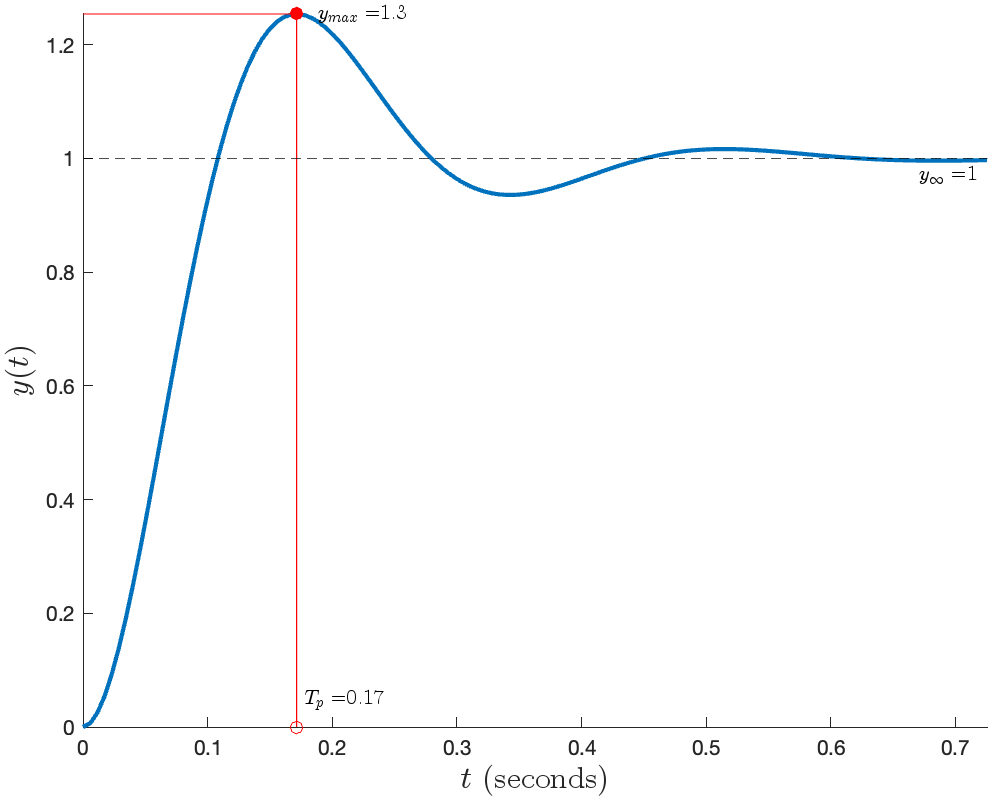

With reference to the figure above, the percent overshoot is defined as

$\%OS=100\frac{y_{max}-y_{\infty}}{y_{\infty}}$,

where $y_{max}=y(T_p)$. That is, the maximum value of $y(t)$ corresponds with the peak time that we determined in the previous section of

$\begin{array}{ll} 
y_{max}
&= 1+e^{-\zeta\pi/\sqrt{1-\zeta^2}
\end{array}
$.

Assuming the input signal is a unit step, $u(t)=1$, the corresponding final value will be $y_{\infty}=A_s=1$. The percentage overshoot formula follows as

$\%OS=100e^{-\zeta\pi/\sqrt{1-\zeta^2}$.

Note that this result generalises for any value of $K$. We can visualise the relationship between damping ratio and percent overshoot of an underdamped second-order system using the code below.

clear

zeta = linspace(0,.95,100);
OS = 100*exp(-zeta.*pi./sqrt(1-zeta.^2));

zeta_ = 0.7;
OS_ = 100*exp(-zeta_*pi/sqrt(1-zeta_^2))

figure,clf,hold on
plot(zeta,OS,LineWidth=2)
plot(zeta_,OS_,'ro',MarkerFaceColor='r')
xlabel('Damping ratio, $\zeta$',Interpreter='latex')
ylabel('Percentage overshoot, $\% OS$',Interpreter='latex')

Note that only $\zeta$ affects the overshoot parameter, not $\omega_n$. We can also determine the required damping ratio if we are given (or can measure) the percent overshoot, by solving the $\%OS$ equation for $\zeta$, namely

$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}$.

This is useful if we are tasked with determining the damping ratio of an unknown transfer function using step response data.

####  Question 3: Determine the percentage overshoot for a damping ratio of $\zeta=0.71$. Provide your answer to two decimal points.

%code block (if required)


### Settling time

**Settling time** is the time it takes for the output response to enter and stay within $2\%$ of the steady-state value, $y_\infty$. Based on this, we set the amplitude of the decaying sinusoid to $0.02$:

$e^{-\zeta\omega_n t}\frac{1}{\sqrt{1-\zeta^2}}=0.02$.

Note that this is a conservative approximation, as we are assuming that the sinusoid experiences a peak at this time point ($\cos(\omega_n\sqrt{1-\zeta^2}t-\phi)=1$). Solving the equation above for $t$ yields

$T_s=\frac{-\ln\left(0.02\sqrt{1-\zeta^2}\right)}{\zeta\omega_n}\approx \frac{4}{\zeta\omega_n}$.

clear
s = tf('s');

K = 2;
zeta = 0.5;
wn = 2;

P = K*wn^2/(s^2+2*zeta*wn*s+wn^2)
[y,t] = step(P);

ea = K*(1+exp(-zeta*wn*t));
eb = K*(1-exp(-zeta*wn*t));

figure,clf,hold on
plot(t,ea,Color='black',LineStyle='--')
plot(t,eb,Color='black',LineStyle='--')

plot(t,y,'-b',LineWidth=2)
yline(K,'-k',['$y_\infty=K=$',num2str(K,2)],Interpreter='latex',LabelVerticalAlignment='bottom')

yline(.98*K,'k-.')
yline(1.02*K,'k-.')

line(4/(zeta*wn)*[1 1],.98*K*[0 1],Color='red')
plot(4/(zeta*wn),.98*K,'ro',MarkerFaceColor='r')
text(4/(zeta*wn),0.05*K,[' T_s\approx',num2str(4/(zeta*wn),2)])
plot(4/(zeta*wn),0,'ro')

num2str(4/(zeta*wn))

xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$y(t)$',Interpreter='latex',FontSize=15)

### Pole locations

We now have expressions that relate peak time, percent overshoot, and settling time to the natural frequency and the damping ratio. Now let us relate these quantities to the location of the poles that generate these characteristics.

clear
K=1
zeta = 0.2;

K = 1

wn = 39;

b = wn*sqrt(1-zeta^2)
a = -zeta*wn

b = 38.2120

a = -7.8000

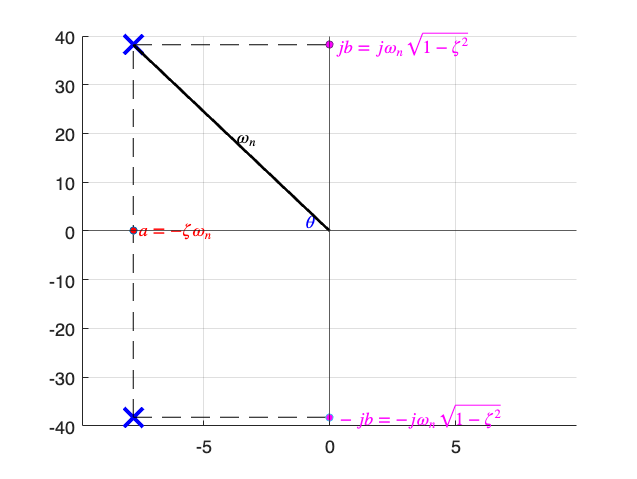

p1 = a+1i*b;
p2 = a-1i*b;

figure,clf,hold on,grid on
xline(0),yline(0)
plot(real(p1),imag(p1),'bx',real(p2),imag(p2),'bx',lineWidth=2,MarkerSize=15)


line([a 0],b*[1 1],'Color','black','LineStyle','--')
text(0,b,'$~jb=j\omega_n\sqrt{1-\zeta^2}$',Interpreter='latex',Color='m')
plot(0,b,'o',MarkerFaceColor='m',MarkerSize=4)
line([a 0],-b*[1 1],'Color','black','LineStyle','--')
text(0,-b,'$~-jb=-j\omega_n\sqrt{1-\zeta^2}$',Interpreter='latex',Color='m')
plot(0,-b,'o',MarkerFaceColor='m',MarkerSize=4)
text(.15*a,.05*b,'$~\theta$',Interpreter='latex',Color='blue')
line(a*[1 1],b*[-1 1],'LineStyle','--','Color','k')
plot(a,0,'o',MarkerFaceColor='r',MarkerSize=4)
text(a,0,'$~a=-\zeta\omega_n$',Interpreter='latex',Color='r')
line([0 a],[0,b],'Color','k','LineWidth',1.5)
text(a/2,b/2,'$~\omega_n$',Interpreter='latex')
xlim([a-2 -a+2])
% axis equal


Ts=4/(zeta*wn)
OS_ = 100*exp(-zeta*pi/sqrt(1-zeta^2))

Ts = 0.5128

t_p=pi/(wn*sqrt(1-zeta^2))

OS_ = 52.6621

y_max=K*(1+exp(-zeta*pi/sqrt(1-zeta^2)))

t_p = 0.0822

y_max = 1.5266

T_pp = 0.0822

T_ss = -0.5128

Recall that we can specify our two underdamped poles as

$p_{1,2}=a\pm jb$.

Consulting the s-plane, we see that $\omega_n=\sqrt{a^2+b^2}$ based on Pythagoras' theorem. Based on this, the angle that subtends the vector from the origin to $p_1$ to the real axis is given by

$\theta = \cos^{-1}\frac{\zeta\omega_n}{\omega_n}=\cos^{-1}\zeta$.

Therefore, the damping ratio can be obtained from the pole-zero map of $P(s)$ by

$\zeta=\cos\theta$.

This aligns with our understanding of system types, as a critically damped system will have a damping ratio of $\zeta=1$ (implying $\theta=0$), and an undamped system will have a damping ratio of $\zeta=0$ (implying $\theta=\frac{\pi}{2}$). Consulting our $\%OS$ formula of

$\%OS=100e^{-\zeta\pi/\sqrt{1-\zeta^2}$,

which is only a function of $\zeta$,this implies that the percentage overshoot will remain unchanged for constant $\theta$, which is equivalent to saying that the ratio of the complex pole's imaginary and real components remains unchanged. 

Additionally, noting that $a=-\zeta\omega_n$ and $b=\omega_n\sqrt{1-\zeta^2}$, we can therefore determine the peak time and settling time using the pole locations as

$T_p=\frac{\pi}{\omega_n\sqrt{1-\zeta^2}}=\frac{\pi}{b}$,

$T_s \approx \frac{4}{\zeta\omega_n}=\frac{4}{|a|}$.

For underdamped systems, we refer to $b$ and $a$ as the *damped frequency of oscillation* and *exponential damped frequency*, respectively. Given the relationships above, we can draw straight lines in the s-plane that correspond to 

- constant peak times (as a result of constant $b$ values),

- constant settling time (as a result of constant $a$ values), and

- constant percentage overshoot (as a result of constant $\zeta=\cos\theta$).

An example is shown in the image below, where $T_{s_2}<T_{s_1}$, $T_{p_2}<T_{p_1}$, and $\%OS_{2}<\%OS_{1}$. Note that this only applies to second-order systems in general.

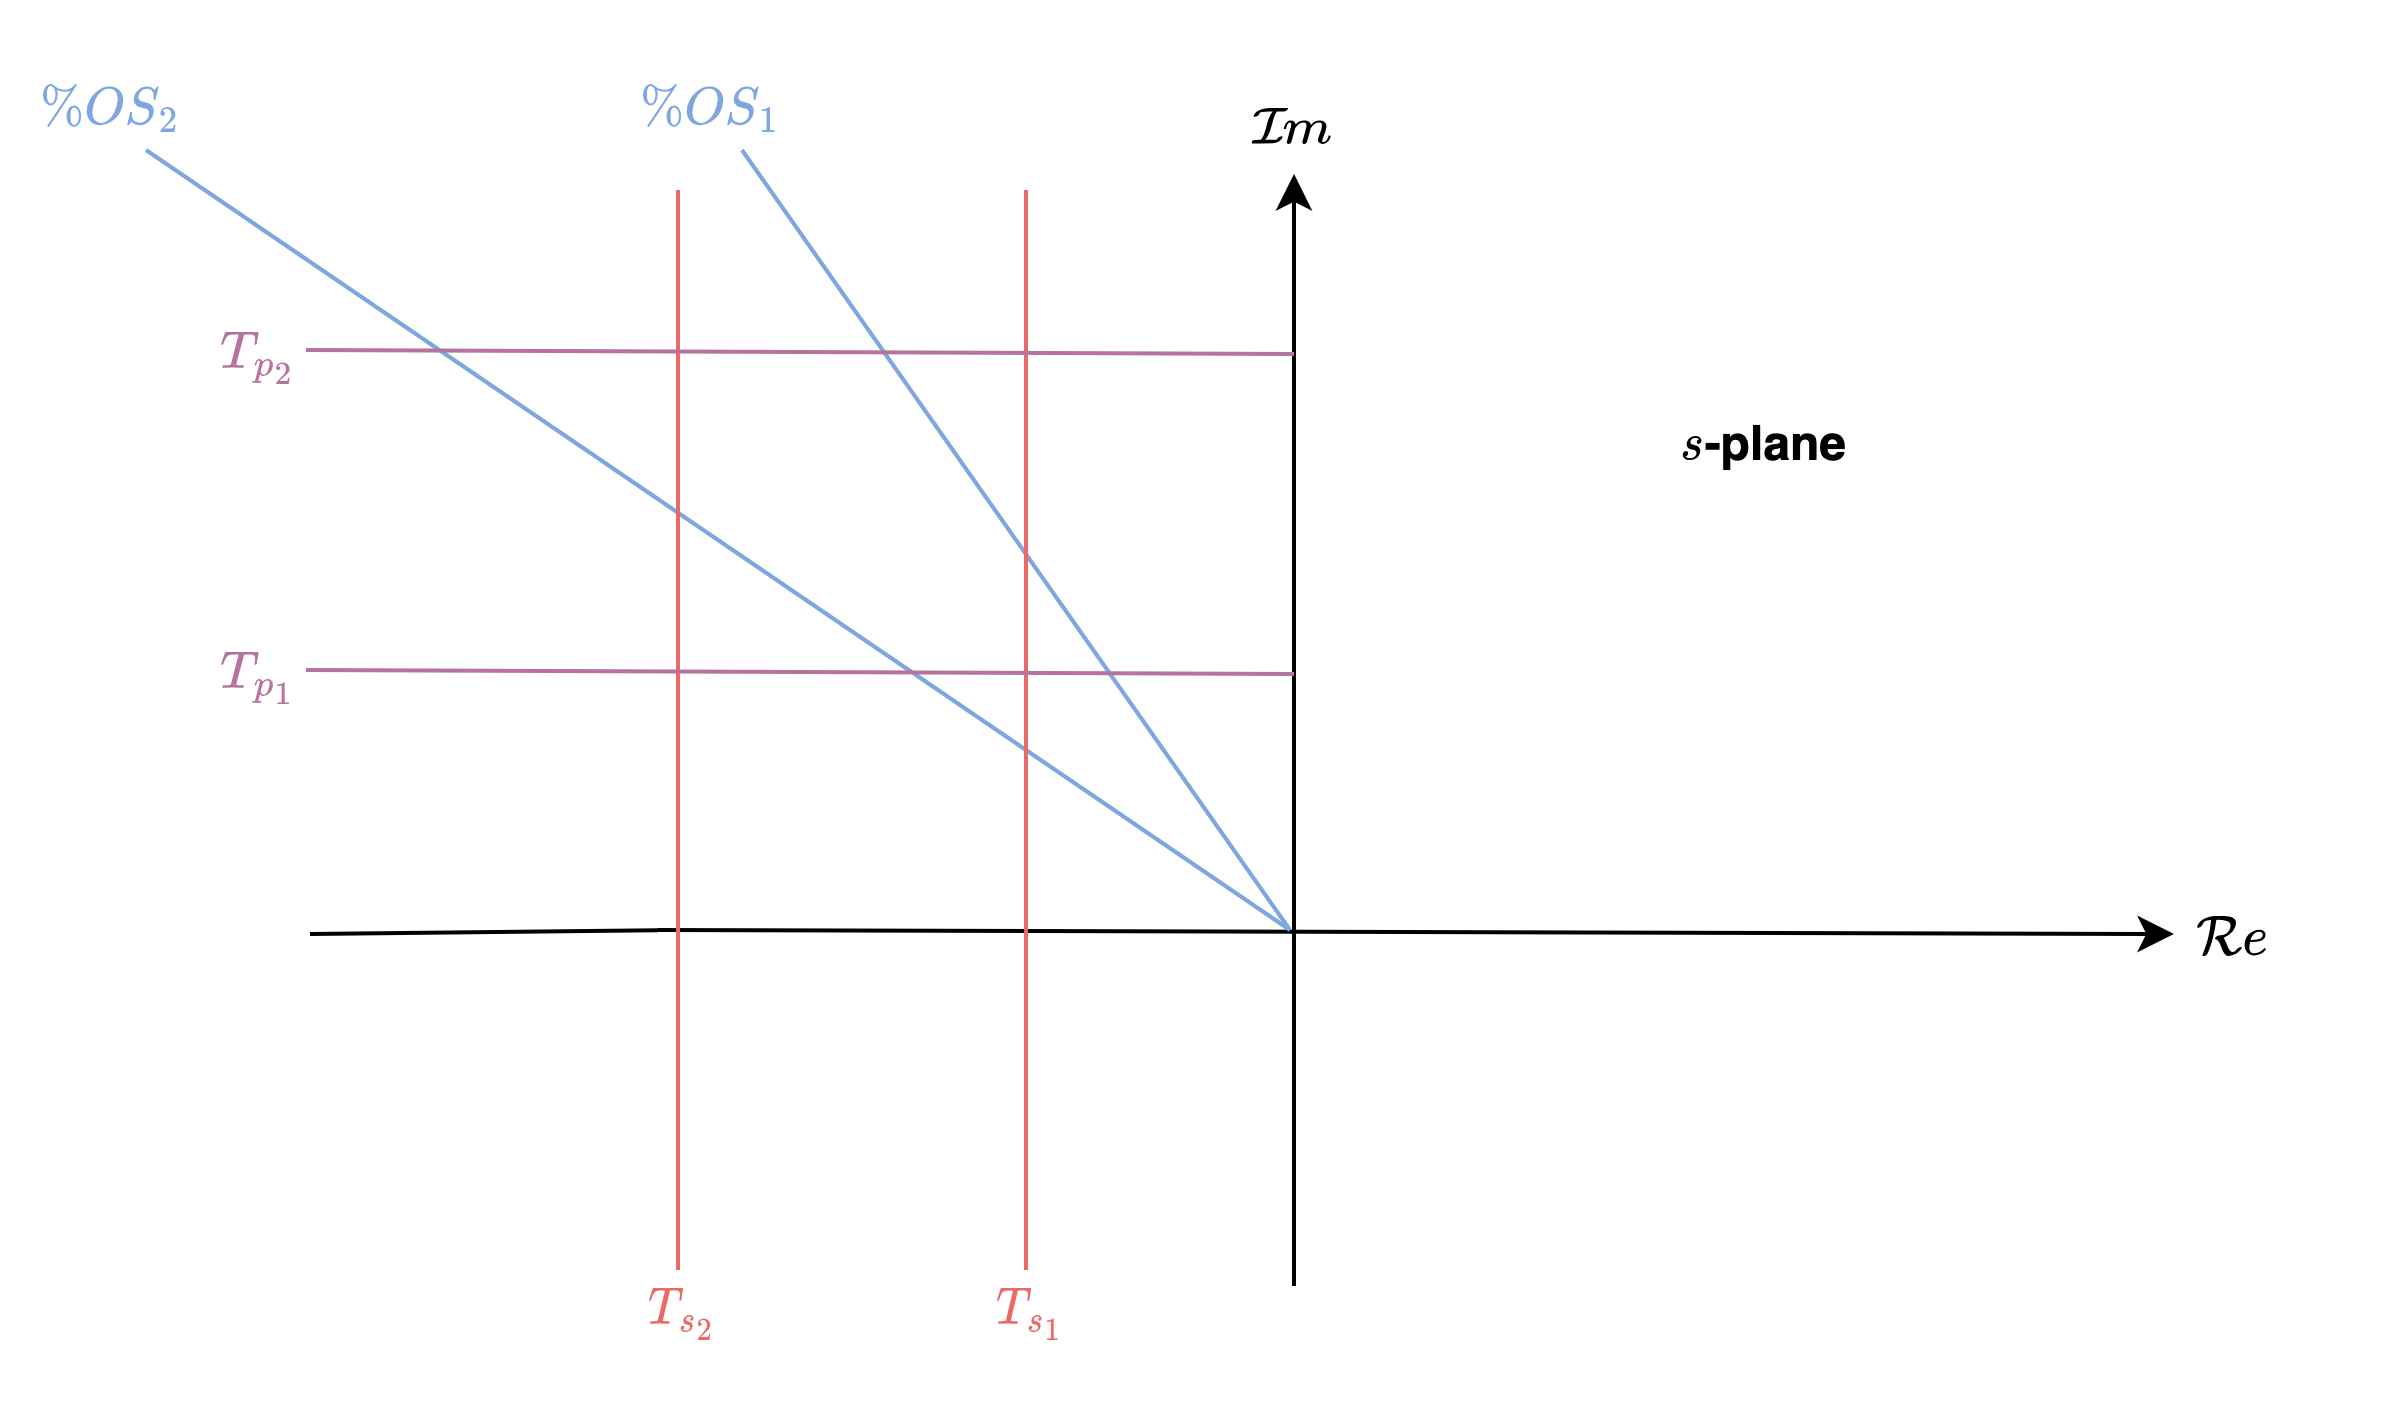

####  Question 4: Which parameter has no effect on the percent overshoot of an underdamped system?

####  Question 5: Which parameter has no effect on the settling time of an underdamped system?

####  Question 6: Which parameter has no effect on the peak time of an underdamped system?

### Determining the transfer function via testing

Just as we obtained the transfer function of a first-order system experimentally, we can do the same for a system that exhibits a typical underdamped second-order response. Given step response data from $P(s)$, we can measure the percent overshoot and peak time. Using this information, we can then solve for the damping ratio and natural frequency using


$$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}$$


and

$\omega_n=\frac{\pi}{T_p\sqrt{1-\zeta^2}}$,

respectively, which collectively fully describes the denominator of $P(s)$. The plant gain, $K$, can be found, as in the first-order system, by finding the ratio of the steady-state output response, $y_\infty$, and value of the input step, $u(t)=\beta$, namely

$K=\frac{y_\infty}{\beta}$.

####   **Task: Use the unit step response data to determine the parameters of the second-order system of the form **$P(s)=\frac{\omega_n^2}{s^2+2\zeta\omega_n s+\omega_n^2}$.

s = tf('s')

A = [-14.2 -100; 1 0];
B = [1 0]';
C = [0 100];
D = 0;
G = ss(A,B,C,D);  

figure,clf,hold on,grid on
[y,t] = step(G);
plot(t,y,lineWidth=2)
%add code here



####  Question 7: What is the value of $\zeta$? Provide your answer to two decimal points.

####  Question 8: What is the value of $\omega_n$? Provide your answer to two decimal points.

## Frequency response

### Introduction

As we have already learnt, the output response is made up of the natural response, $y_n(t)$, and forced response, $y_f(t)$, namely.

$y(t)=y_n(t)+y_f(t)$,

where the profile of the forced response matches that of the input signal, $u(t)$. We have also shown that in steady-state, the output response of a stable, linear system will be equal to the forced response, 

$y_{ss}(t)=y_f(t)$,

which has the same signal profile as that of the corresponding input signal. By extension, if the input signal to a system is sinusoidal, then the steady-state output response will also be sinusoidal with the same frequency, but with a different amplitude and phase angle in general. We can use this information to develop a *frequency-based* understanding of our system, as we will now show.

### Definition

The **frequency response** is a set of complex numbers, parameterised by frequency $\omega$, which relate input sinusoids to output sinusoids under steady-state conditions (when the natural response has decayed sufficiently). Specifically, if an input sinusoid with frequency $\omega$ is injected into $P(s)$, then after such time that the natural response has decayed to zero, the output response will also be a sinusoid with frequency $\omega$, but with different gain and phase as a result of the *contribution* of phase and gain from $P(s)$. An input-output visualisation of the concept of the frequency response is shown in the image below.

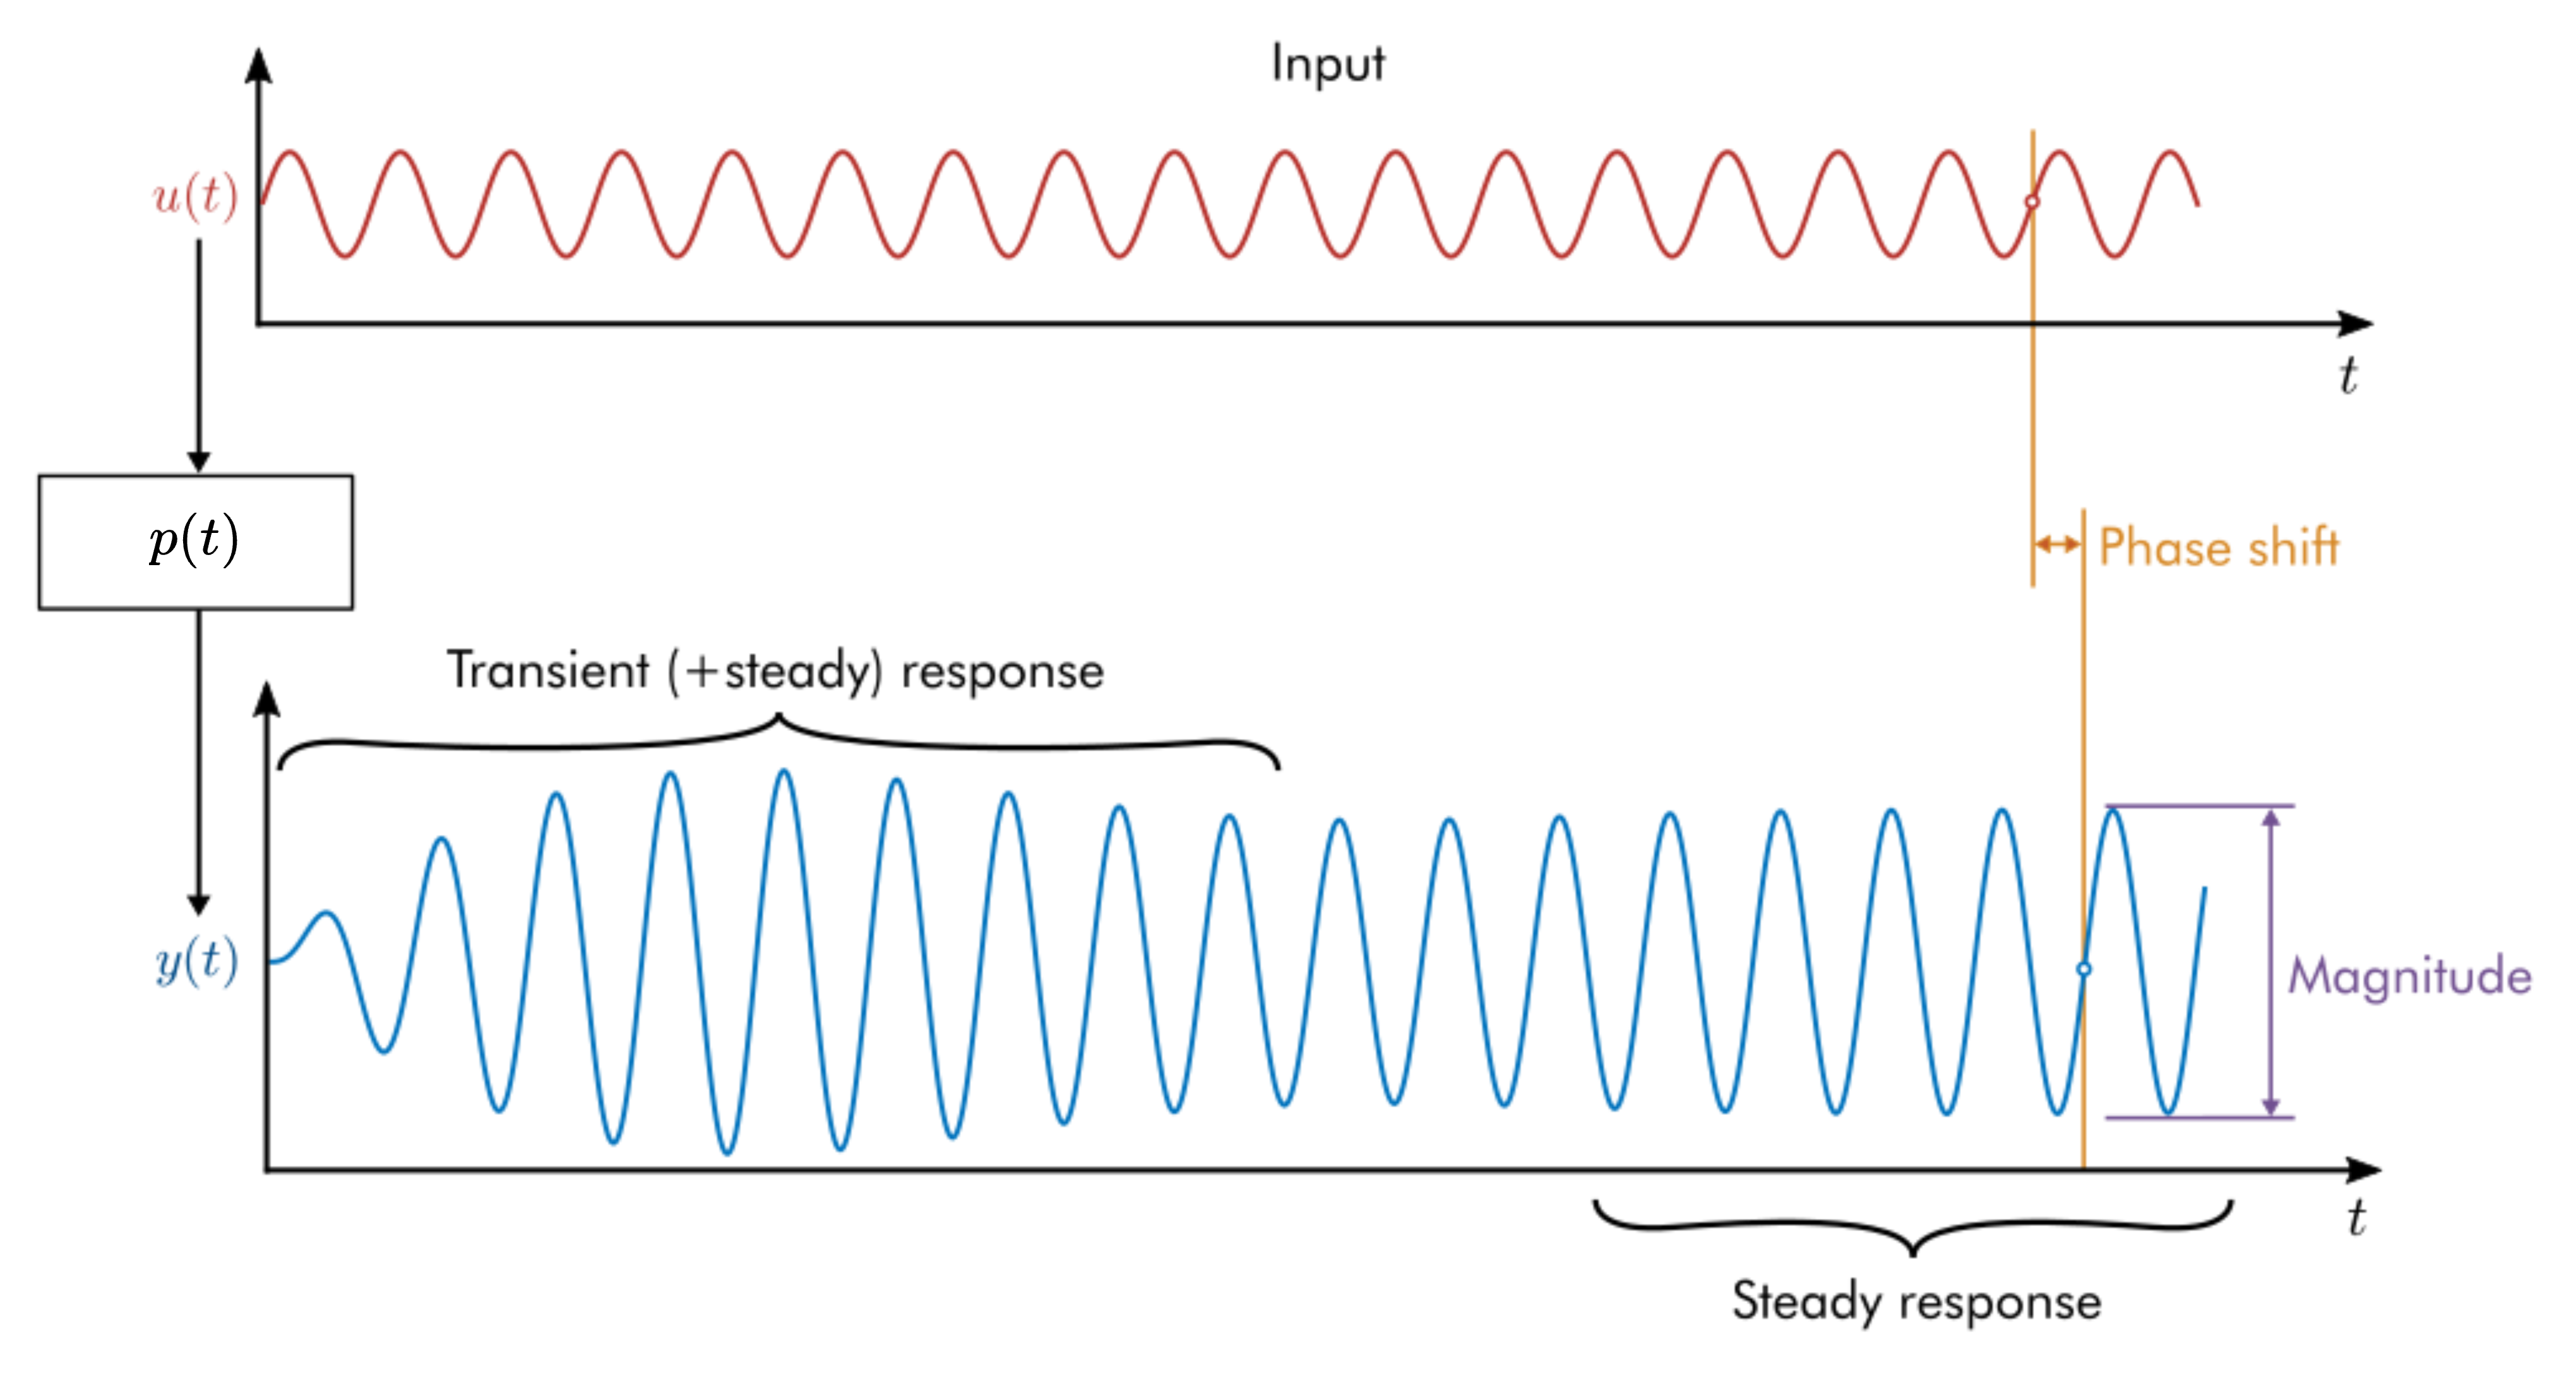

While not yet obvious, the frequency response contains invaluable information that we will use to conduct closed-loop analysis and control design in later chapters. The following section provides a formal derivation of the frequency response.

### Deriving the frequency response

Consider an input signal in the form of a co-sinusoid with unit amplitude,

$u(t)=\sin(\omega t)$.

The corresponding Laplace transformed signal is given as

$U(s)=\frac{\omega}{s^2+\omega^2}$.

Applying our sinusoidal input signal to system $P(s)$ results in an output response of

$Y(s)=P(s)U(s)=P(s)\frac{\omega}{s^2+\omega^2}$.

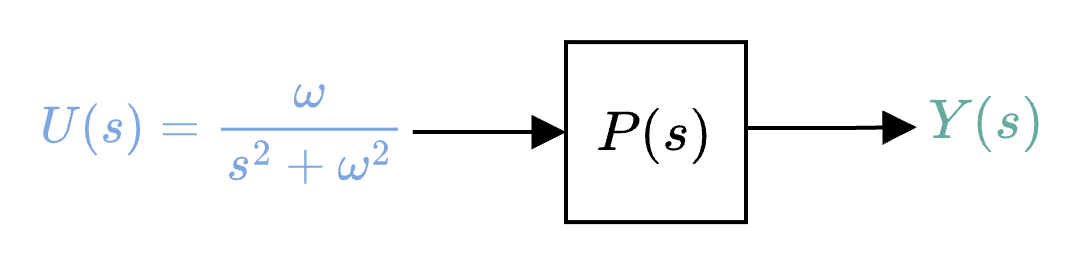

Using partial fraction expansion, the output response can be represented as


$$\begin{array}{rl}
Y(s)
&=P(s)\frac{\omega}{s^2+\omega^2},\\
&=P(s)\frac{\omega}{(s+j\omega)(s-j\omega)},\\
&=\frac{A}{s+j\omega}+\frac{B}{s-j\omega}+\text{Partial fraction terms from } P(s).
\end{array}$$


Using the residual formula we can determine $A$ and $B$ using

$A = \lim_{s\rightarrow -j\omega}\frac{\omega}{s-j\omega}P(s)=\frac{jP(-j\omega)}{2}$,

$B = \lim_{s\rightarrow j\omega}\frac{\omega}{s+j\omega}P(s)=\frac{-jP(j\omega)}{2}$.

At steady-state, when the natural response tends to zero (assuming the system is stable), the steady-state output response (made up only of the forced response) can be written as


$$\begin{array}{rl}
Y_{ss}(s)
&=\frac{A}{s+j\omega}+\frac{B}{s-j\omega},\\
&=\frac{jP(-j\omega)/2}{s+j\omega}-\frac{jP(j\omega)/2}{s-j\omega},\\
&=\frac{j\frac{M_P}{2}e^{-j\phi_P}}{s+j\omega}-\frac{j\frac{M_P}{2}e^{j\phi_P}}{s-j\omega},\\
&=\frac{\frac{M_P}{2}e^{-j(\phi_P-\pi/2)}}{s+j\omega}+\frac{\frac{M_P}{2}e^{j(\phi_P-\pi/2)}}{s-j\omega},\\
\end{array}$$


where $M_P(\omega) = |P(j\omega)|$, and $\phi_P(\omega)=\angle P(j\omega) = \tan^{-1}P(j\omega)$. Note that, strictly speaking, we should use `atan2` instead of $\tan^{-1}$. The steady-state time-domain output response can be determined using $y_{ss}(t)=\mathcal{L}^{-1}\{Y_{ss}(s)\}$, which yields


$$\begin{array}{rl}
y_{ss}(t)
&=\frac{M_P(\omega)}{2}e^{-j(\omega t+\phi_P(\omega)-\pi/2)}+\frac{M_P(\omega)}{2}e^{j(\omega t+\phi_P(\omega)-\pi/2)},\\
&={M_P(\omega)}\cos\left[\omega t+\phi_P(\omega)-\pi/2\right],\\
&={M_P(\omega)}\sin\left[\omega t+\phi_P(\omega)\right].
\end{array}$$


The sinusoidal output response at steady-state is therefore determined by scaling the input sinusoid of $u(t)=\sin(\omega t)$ by the plant magnitude $M_P(\omega)$, and adjusting the phase of the input sinusoid by the plant phase angle, $\phi_P(\omega)$.

In general, it may be shown that if the input sinusoid has a magnitude of $M_U$ and phase shift of $\phi_U$, namely

$u(t)=M_U\sin(\omega t+\phi_U)$,

 then the output response at steady-state follows as


$$\begin{array}{rl}
y_{ss}(t)
&={M_P(\omega)M_U}\sin\left[\omega t+\phi_P(\omega)+\phi_U\right],\\
&={M_Y(\omega)}\sin\left[\omega t+\phi_Y(\omega)\right],
\end{array}$$


where

$M_Y(\omega)=M_P(\omega)M_U$, 

and

$\phi_Y(\omega)=\phi_P(\omega)+\phi_U$.

As with the case when $u(t)=\sin(\omega t)$, the plant dynamics will scale the input sinusoid by $M_P(\omega)$, and shift the response by $\phi_P(\omega)$. Based on the above equations, we can also determine the magnitude and phase behaviour of our plant using

$M_P(\omega)=\frac{M_Y(\omega)}{M_U}$,

and 

$\phi_P(\omega)=\phi_Y(\omega)-\phi_U$,

respectively. $M_P(\omega)$ is referred to as the **magnitude response** of $P(s)$, and $\phi_P(\omega)$ is referred to as the **phase response**. Recall that we determined the magnitude and phase response using  $M_P(\omega) = |P(j\omega)|$, and $\phi_P(\omega)=\angle P(j\omega) = \tan^{-1}P(j\omega)$. The term $P(j\omega)$ therefore inherently contains the magnitude and phase response information that we are interested in. As such, the important result that we will make use of for the remainder of this course is that the **frequency response** of any stable system is determined by evaluating $P(s)$ as the Laplace operator, $s$, tends to infinity,

$P(j\omega)=M_P(\omega)e^{j\phi_P(\omega)}=\lim_{s\rightarrow j\omega}P(s)$.

####  Question 9: Determine the frequency response of $L(s)=\frac{10}{2s+1}$ by hand.

### Visualising frequency response

Based on the previous section, we can determine the frequency response using

$P(j\omega)=\lim_{s\rightarrow j\omega}P(s)$,

which means that we are simply swapping $'s'$ terms in the transfer function with $'j\omega'$ terms. The frequency response can be thought of simply as a complex number at every frequency point, $\omega$, which has the representation of 

    $P(j\omega)=a(\omega)+jb(\omega)$.

This is commonly referred to as the rectangular form.

%Example
s = tf('s');
P = 1/(1+s);

W = 1:10;
Pw = frd(P,W) %frequency response of P(s) for omega=1:10;

As shown in the previous section, we can also represent $P(j\omega)$ in polar form

$P(j\omega)=|P(j\omega)|e^{\angle P(j\omega)}=M_P(\omega)e^{ \phi_P(\omega)}$,

where the polar form is related to the rectangular form using

$|P(j\omega)|=\sqrt{a^2(\omega)+b^2(\omega)}$,

and

$\angle P(j\omega) = \tan^{-1}\left(\frac{b(\omega)}{a(\omega)}\right)$.

P_mag = abs(Pw) %magnitude response of P
P_angle = angle(Pw) %phase response of P

The frequency response will be able to provide us with important information about the system under consideration. The easiest approach to interpret information from the frequency response is to plot the information in a way that allows for easy understanding of the system behaviour. We will consider three such approaches of visualisation frequency response, namely Nyquist diagrams, Bode diagrams, and log-polar plots, but for this Virtual Lab we will exclusively focus on Bode diagrams.

### Bode diagram

A common means of visualising the magnitude and phase response of $P(s)$ is to plot $|P(j\omega)|$ and $\angle P(j\omega)$ separately against frequency. As we will show later, there is benefit in plotting the magnitude of $P(j\omega)$ in decibels (dB) vs logarithmic frequency ($\log \omega$). In the case of the phase response we plot phase angle (in degrees) vs $\log \omega$. This type of plot is known as a **Bode diagram**, as shown below.

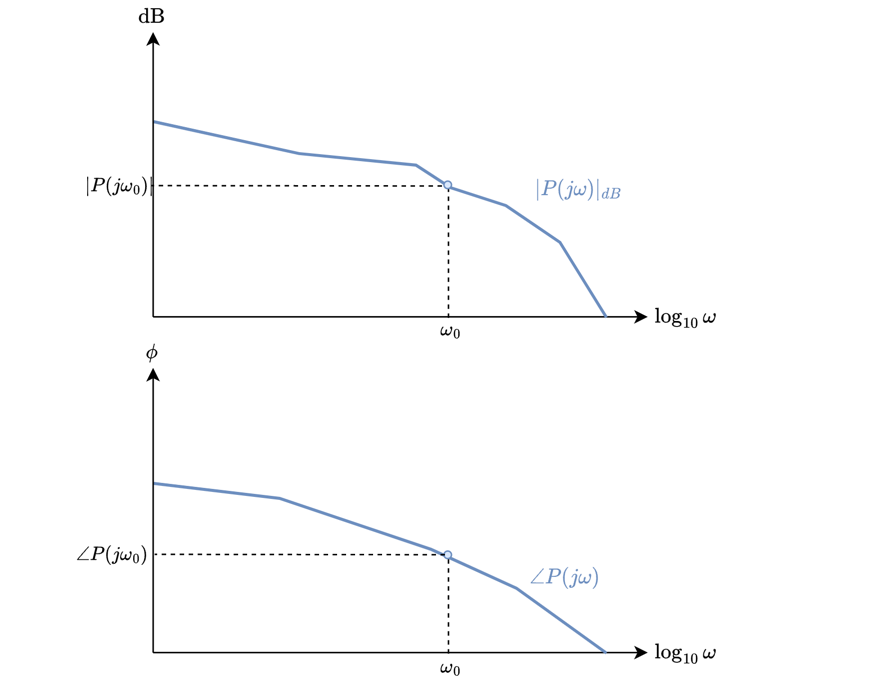

We determine the *logarithmic* magnitude using

$|P(j\omega)|_{db}=20\log_{10}|P(j\omega)|$.

The phase response of $P(j\omega)$, plotted in degrees, is determined using 

$\angle P(j\omega)=\tan^{-1}\left( \frac{b(\omega)}{a(\omega)}\right)\frac{180}{\pi}$.

The decibel representation is useful as we can exploit the following logarithmic identities:


$$\log_{10}(AB)=\log_{10}A+\log_{10}B$$



$$\log_{10}(A/B)=\log_{10}A-\log_{10}B$$


In other words, multiplication in *arithmetic* units is equivalent to addition in *logarithmic* units. This extends to any number of product or division operations. Similarly, because multiplication by a complex number is equivalent to a rotation and scaling, we can use the following identities when determining phase angle:


$$\angle \{c(j\omega)d(j\omega)\}=\angle c(j\omega) + \angle d(j\omega)$$



$$\angle \{c(j\omega)/d(j\omega)\}=\angle c(j\omega) - \angle d(j\omega)$$


This extends to any number of product or division operations.

####  Question 10: Determine the magnitude response (in dB) of $L(s)=\frac{10}{2s+1}$ by hand.

####  Question 11: Determine the phase response (in radians) of $L(s)=\frac{10}{2s+1}$ by hand.

### Understanding the frequency response

The frequency response describes the gain and phase behaviour of the system under consideration. The magnitude response (or gain), $|P(j\omega)|$, tells us how input signals are amplified/reduced when passing through the system, and the phase response, $\angle P(j\omega)$, tells us how output signal will lead or lag the input signal. We can use this information to understand the input-output relationship between signals in the frequency domain. 

The following code below simulates the response of the system 


$$P(s)=\frac{1}{s^2+s+1}$$


to sinusoidal inputs of different frequencies. The black boxes on the Bode plots indicate how the steady-state output should be scaled and shifted for a sinusoidal input of the specified frequency, $\omega_u$. As we are only interested in the steady-state response when assessing frequency response, the output response shown below has truncated the output response to only show the periodic behaviour (at steady-state).

clear
s = tf('s');
P = 1/(s^2 + 1*s + 1);                %Our second-order system

omega_u =1.59;      %Input sinusoid frequency in rad/s
t = 0:0.1:120;                          %Time vector
u = sin(omega_u*t);                      %Input sinusoid
[y,t] = lsim(P,u,t);                    %Use lsim to generate output response
f3 = figure;
subplot(1,2,1)
subplot(1,2,2)                          %Plot two figures in parallel
[gain,phi] = bode(P,omega_u)              %Get frequency response of P at omega_u

bode(P,omega_u,'ks')                     %Plot black box on bode diagram.
grid
hold on;                                %Hold figure so that subsequent plots dont clear figure
bode(P,{0.1,10});                       %Plot frequency response for w=0.1 rad/s to w=10 rad/s
subplot(1,2,1)
plot(t,u,'r',t,y,'b')                   %Plot time-domain input and output signals
legend('$u(t)$','$y(t)$',Interpreter='latex')
grid
axis([80 t(end) -10 10])
clf(f3)

####  Question 12: Using the code block above, determine the frequency, $\omega_u$, at which the system has a phase *lag* of $90^\circ$. 

%Code block to confirm answer (if required)


What you should have observed from the simulation above is that for sinusoidal inputs with low frequencies, the output response will approximately track the input, whereas at higher frequencies, the output magnitude becomes attenuated and the phase lag (effective delay) increases dramatically. 

####  Question 13: What type of filter does $P(s)$ resemble?

####  Question 14: Submit your completed Virtual Lab 5 live script. **The file name must be appended with your student number, e.g. VirtualLab5_SMTJOH999.slx.**  

We will explore the frequency response in more detail in subsequent Virtual Labs! This concludes Virtual Lab 5.